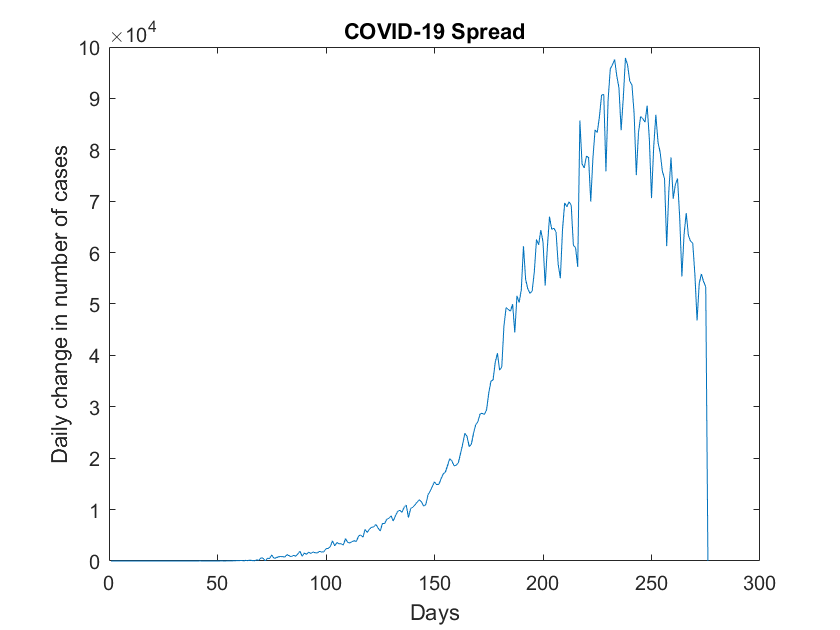

% Acquiring data from excel sheet
a=readtable('covid.xlsx');
%Considering the data pertainig to india
A=a(145,:);
% Removing unwanted columns like province, contry name and some initial
A=removevars(A,1:4);
% Converting table to array for further processing
A=table2array(A);
% Computing daily change in cases from daily cases
for i=1:length(A)-1
    X(i)=A(i+1)-A(i);
end
% Y is a vector that indicates day no.
Y=1:276;
% Plotting the sampled phenomenon
plot(Y,X);
xlabel('Days')
ylabel('Daily change in number of cases')
title('COVID-19 Spread')

x=X;
Y=reshape(Y,[],1);
X=reshape(X,[],1);
% K-Means Algorithm
% idx is a vector of length same as X which specifies the cluster no. to
% which the corresponding data point belongs to
% C is a vector of length K(no .of clusters) which has cluster centroid
% values
[idx,C] = kmeans([X],8); 
C

C = 	1.0e+04 *

    6.5014
    0.1149
    7.6887
    5.2370
    1.2681
    9.5173
    8.6484
    2.9870


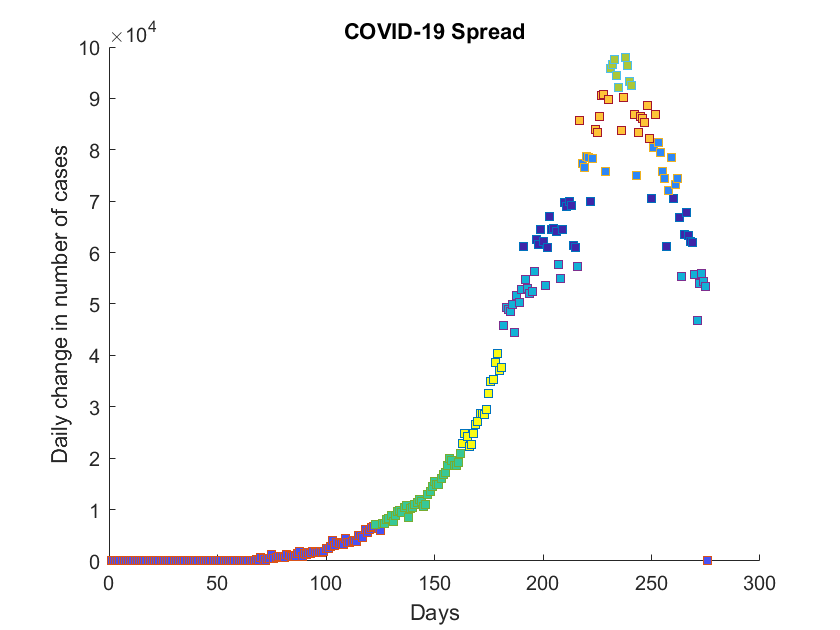

% Color map to differentiate the clusters
cmap = parula(8);
clf; hold on 
xlabel('Days')
ylabel('Daily change in number of cases')
title('COVID-19 Spread')
% Plot with the clusters indicated
for i=1:8
    k = find(idx==i);
    plot(Y(k),X(k),'s','MarkerFaceColor',cmap(i,:)); 
end 
hold off 

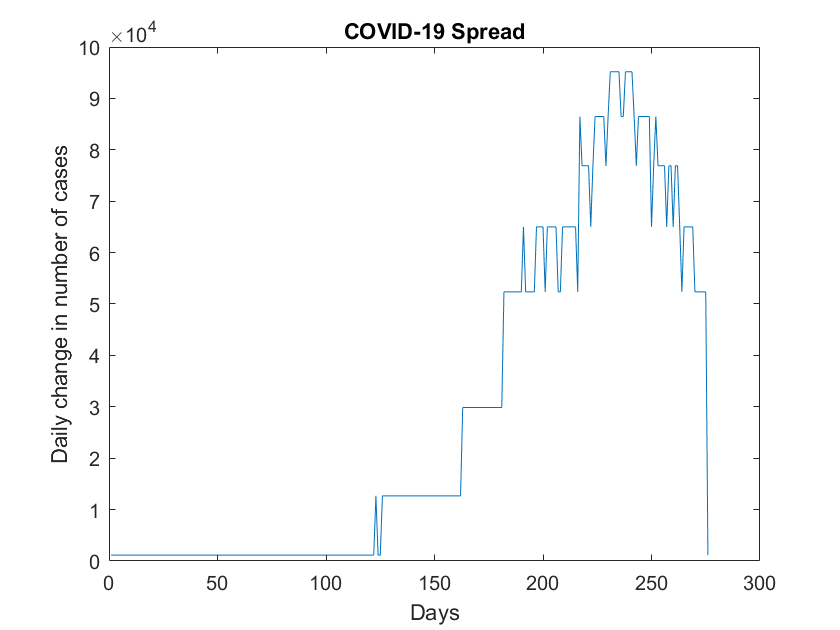

% Mapping the data points to centre of cluster which they belong to, i.e)
% mapping to the values in the Quantised set
for i=1:276
    K(i)=C(idx(i));
end
% Plot of Quantized signal
plot(Y,K)
xlabel('Days')
ylabel('Daily change in number of cases')
title('COVID-19 Spread')

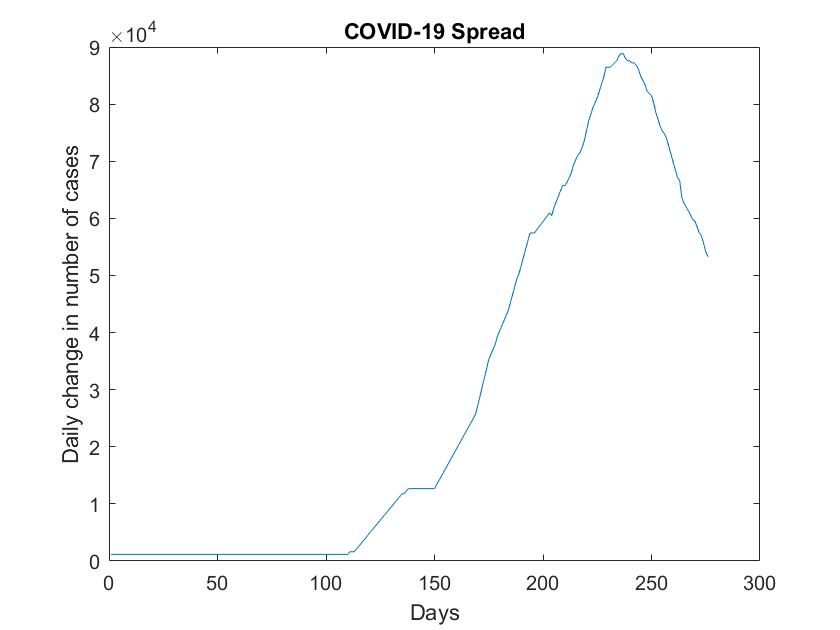

% Reconstructing the clusters from cluster centroids is a strenuous task
% We do a median filtering of Quantized signalfor reconstruction
k=movmean(K,25);
plot(Y,k)
xlabel('Days')
ylabel('Daily change in number of cases')
title('COVID-19 Spread')